# LQG Control for the unstable position

We want to stabilize the pendolum **on the unstable equilibrium position** by **acting on the control variable** "V" (voltage).

clear 
% close all 

parameters = 1;      % 0 = nominali; 1 = identificati

% System parameters

if parameters == 0
    B_p = 0.0024; % Pendulum viscous damping coeffi- cient as seen at the pivot axis N*m*s/rad
    B_r = 0.0024; % Rotary arm viscous damping coeffi- cient as seen at the pivot axis N*m*s/rad
    J_a = 0.0020; % Rotary arm moment of inertia about pivot m^2
    J_p = 0.0012; % Pendulum moment of intertia about center of mass Kg*m^2
    l_p = 0.156;  % Distance from pivot to center of mass m
    m_p = 0.127;  % Mass of pendulum Kg
    r = 0.216;    % Rotary arm length from pivot to tip m
    J_T = (J_a*m_p*l_p^2 + J_p*m_p*r^2 + J_a*J_p);
    g = 9.81;     % gravitational acceleration m/s^2

    K_g = 70;      % High-gear total gear ratio
    R_m = 2.6;     % Ohm
    eta_g = 0.90;  % Gearbox efficiency
    eta_m = 0.69;  % Motor efficiency
    k_m = 7.68e-3; % Motor back-emf constant V/(rad/s)
    k_t = 7.68e-3; % Motor current-torque constant N*m/A
else
    % Valori identificati
    load th_id
    B_p = id_param(1); % Pendulum viscous damping coeffi- cient as seen at the pivot axis N*m*s/rad
    B_r = id_param(2); % Rotary arm viscous damping coeffi- cient as seen at the pivot axis N*m*s/rad
    J_a = id_param(3); % Rotary arm moment of inertia about pivot m^2
    J_p = id_param(4); % Pendulum moment of intertia about center of mass Kg*m^2
    l_p = id_param(5);  % Distance from pivot to center of mass m
    m_p = id_param(6);  % Mass of pendulum Kg
    r = id_param(7);    % Rotary arm length from pivot to tip m
    J_T = (J_a*m_p*l_p^2 + J_p*m_p*r^2 + J_a*J_p);
    g = id_param(8);     % gravitational acceleration m/s^2

    K_g = id_param(9);      % High-gear total gear ratio
    R_m = id_param(10);     % Ohm
    eta_g = id_param(11);  % Gearbox efficiency
    eta_m = id_param(12);  % Motor efficiency
    k_m = id_param(13); % Motor back-emf constant V/(rad/s)
    k_t = id_param(14); % Motor current-torque constant N*m/A
end

% Limits for Input and Outputs:
theta_max = 45;     % Maximum theta rotation[deg]
alpha_max = 15;     % Maximum alpha deflection [deg]
voltage_max = 10;    % Maximum control voltage


## State space

[A,B,C,D] = SS_Matrices_Voltage_Unstable(B_p,B_r,J_T,J_a,J_p,K_g,R_m,eta_g,eta_m,g,k_m,k_t,l_p,m_p,r);

% State-space model

% LQ servono queste due righe, LQG vanno commentate
% C = eye(4);
% D = zeros(4,1);

ss_sys = ss(A,B,C,D);

% Transfer functions
tf_sys = tf(ss_sys);

pole(ss_sys); % we compute poles 
tzero(ss_sys(1)) % and zeros

ans =     6.2884
   -6.7456


tzero(ss_sys(2)) % and zeros

ans = 1.0e-14 *

    0.1308
         0


r_ank = rank([A B; C D]); % Rank = 5, so since n = 4 then p must be 1


Then, place integrators on the outputs' tracking errors to guarantee robust asymptotic zero-error tracking of constant references.

**Remark**: Since there is only one control variable ($m=1$) we can place at most one integrator.

### Place the integrator on the first output


$$\dot{\eta} =y_1^0 -y_1 =\delta y_1^0 -\delta y_1 =\delta y_1^0 -C_1 \delta x$$



$$\delta \dot{x} =A\delta x+B\;\delta u$$


Therefore the enlarged system reads as


$$\dot{\tilde{x} } =\left\lbrack \begin{array}{cc}
A & 0\\
-C_1  & 0
\end{array}\right\rbrack \tilde{x} +\left\lbrack \begin{array}{c}
B\\
0
\end{array}\right\rbrack \delta u+\left\lbrack \begin{array}{c}
0\\
I
\end{array}\right\rbrack \delta y^0$$


Where $\tilde{x} =\left\lbrack \begin{array}{c}
\delta x\\
\eta 
\end{array}\right\rbrack$ is the enlarged state.

A_tilde = [ A,          zeros(4, 1);
            -C(1, :),   0 ];
B_tilde = [ B;
            0 ];
M_tilde = [ zeros(4, 1);
            1               ];

## 3) LQ Controller Design

*Considering the same scheme adopted in the previous point, implement an *${\textrm{LQ}}_{\infty }$ controller*. *

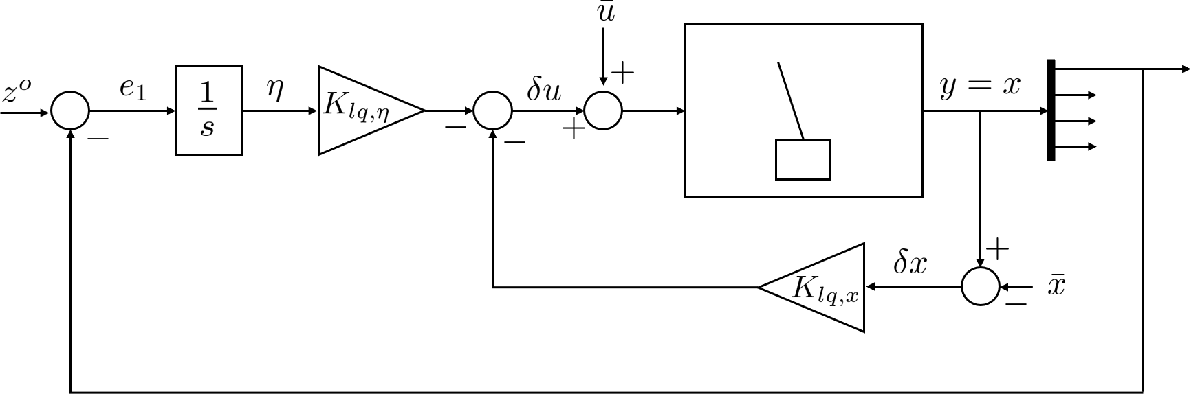

**Recall that you need to subtract **$\bar{x}$** since you are using a linearized system around the equilibrium position!**

Remember that we formulated the whole **optimal control problem **in such a way that the state is lead to a 0 value: $x\to 0$ this is the reason why we subtract $\bar{x\;}$

Find the ${\textrm{LQ}}_{\infty }$ control law for the enlarged system $\;\Longrightarrow$   same scheme, different way to compute the gains

Function: `lqr(A, B, Q, R)`

For the time being, we assume 

errore_max_theta = 10; % deg
errore_max_alpha = 8; % deg

% et = errore_max_theta*pi/180; % rad
% ea = errore_max_alpha*pi/180; % rad

et = errore_max_theta; % deg
ea = errore_max_alpha; % deg

et_d = 1000000;
ea_d = 1000000;
ev = 1000;

Q_lq = diag([1/(et^2), 1/(ea^2), 1/(et_d^2), 1/(ea_d^2), 1]); % 5x5 matrix since we have 5 states describing the system.

Per tarare i pesi fare 1/errore_voluto^2

Goal: Theta veloce con alpha accettabile (decidiamo noi quando è acettabile es: 1 deg, 5 deg)

By writing the Q matrix as above it means that we are basically weighting more the speeds rather than positions. This means that the optimization procedure will penalize changes on speeds more with respect than changes in position. This is meaningful since we are working with a linearized system, so we don't want the system variables to have an high rate of change. With large speed you risk going outside the linearized region.

**General Remark: **when working with linearized systems is better to keep derivatives bounded!

The weight of the integrator is more **trial and error**.

R_lq = 1/(ev^2);

To implement the ${\textrm{LQ}}_{\infty }$ we need to check the **implementation conditions**, so that

- The pair $\left(\tilde{A} ,\tilde{B} \right)$is reachable  $\Longrightarrow$  OK

rank(ctrb(A_tilde, B_tilde)) % controllability matrix

ans = 5

- The pair $\left(\tilde{A} ,{\tilde{C} }_q \right)$is observable, where $C_q^T \;C_q =Q\;\;\Longrightarrow$  OK

Cq = sqrt(Q_lq); % We can do this because Q_lq is diagonal!!
rank(obsv(A_tilde, Cq))

ans = 5

Since the ${\textrm{LQ}}_{\infty }$ law is **stabilizing**, we can compute the corresponding gain by solving the steady-state Riccati equation. 

We can do so using the `lqr` command:

K_lq = lqr(A_tilde, B_tilde, Q_lq, R_lq)

K_lq = 1.0e+03 *

   -0.4645    0.7840   -0.1035    0.1145    1.0000


Eventually we can partition the gain `K_lq` as 

K_lqx   = K_lq(:, 1:4);
K_lqeta = K_lq(:, 5);

### Implementation

% open('Pendulum_LQ.slx');

From animation we can see how the pendulum reaches the equilibrium position after a transitory.

Than what happens is that the integrator allows to bring the position to the constat reference value. If we apply a perturbation we can see that the system will still end up to the constant reference position.

Moreover we can see that if we apply a sufficiently high disturbance, the cart will go to the set position, however the angle might be different from zero because a disturbance is acting on the system and we have no integrator to bring the angle to 0.

You can also check what happens to your control system if you inculde saturation of actuators (maximum voltage you can apply).

## 4) LQG (LQ + Kalman Filter)

Usually we don't have a feedback of all states available. 

**Note that we design the Kalman filter only for the original system and not for the augmented one**.

*Design and implement a Kalman Filter to estimate the states of the system, assuming that we only measure the position of the cart *$z$* and the angle of the beam.*

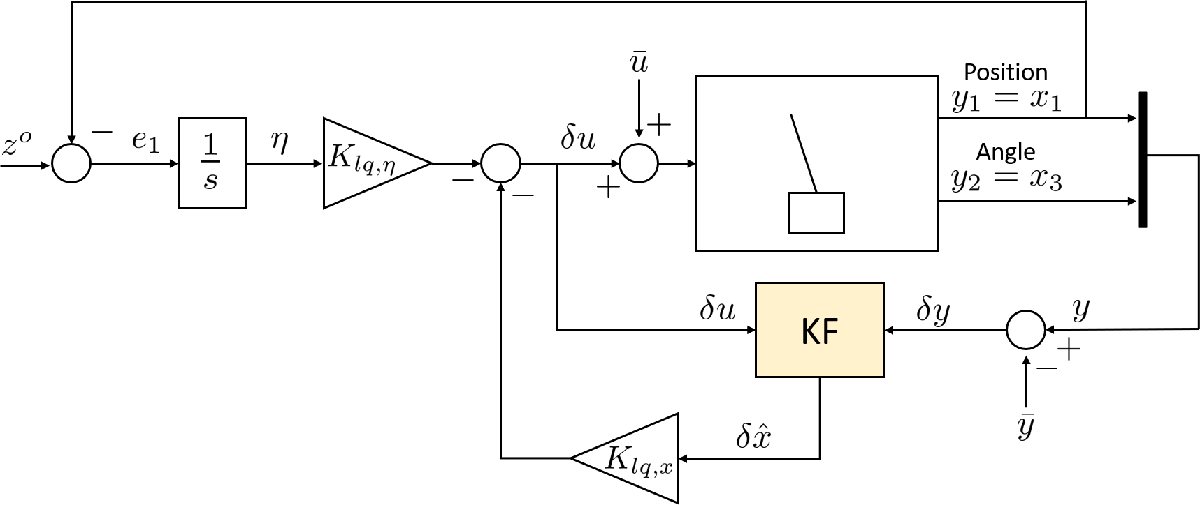

**Remark****:** We only need to estimate $\delta x=\left\lbrack \begin{array}{cccc}
\delta x_1  & \delta x_2  & \delta x_3  & \delta x_4 
\end{array}\right\rbrack \ldotp$ The** state **$\eta$** is known** and does not neet to be estimated. 

Therefore we design the Kalman Filter for the following system:


$$\left\{ \begin{array}{l} 
\delta \dot{x} = A \, \delta x + B \, \delta u + \nu_x \\
\delta y = C \, \delta x + \nu_y
\end{array}\right.
\qquad \qquad  \begin{array}{l} \nu_x \,\tilde\, \text{WGN}(0, Q_{kf}) \\ \nu_y \,\tilde\, \text{WGN}(0, R_{kf})  \end{array}$$


Note we need to write our original system in the conditions suitable for applying the Kalman Filter Theory!

**Since we know the state of the integrator we don't need to estimate it.**

Q_kf = diag([0.1, 0.1, 1, 1]);  % The models of state 1 (theta) and state 2 (alpha) are the most reliable so their variance is lower
R_kf = 0.1;                     % We trust the measurements more than the linearized model

**Remark: **If in ${\textrm{LQ}}_{\infty \;}$we weighted more the state variables we wanted to bound more, here we weight less the state variables we want our optimization procedure to rely on more! **DUALITY**

**usually these covariance matrices are not known so you just put values almost by trial and error.**

### Observability check

- The pair $\left(A,B_{q\_\textrm{kf}} \right)$ must be reachable  $\Longrightarrow$  OK ---> to guarantee the observability problem can be solved

B_qkf = sqrt(Q_kf); % We can do this because Q_kf is diagonal!!

rank(ctrb(A, B_qkf))

ans = 4

- The pair $\left(A,C\right)$ must be observable  $\Longrightarrow$  OK ---> to guarantee asymptotic stability of the observer

rank(obsv(A, C))

ans = 4

The dynamics equation of the Kalman Filter is


$$\delta \overset{\circ }{\hat{x} } =A\;\delta \hat{x} +B\;\delta u+L_{\textrm{kf}} \left(\delta y-C\;\delta \hat{x} \right)=\left(A-L_{\textrm{kf}} \;C\right)\delta \hat{x} +\left\lbrack \begin{array}{cc}
B & L_{\textrm{kf}} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\delta u\\
\delta y
\end{array}\right\rbrack$$


Where the gain $L_{\textrm{kf}}$ is the retrieved solving the steady-state Riccati Equation

**Remark: **Note again that the output of the filter is the estimated variation of the state with respect to the equilibrium values.

L_kf = lqr(A.', C.', Q_kf, R_kf).'

L_kf =     1.0366    0.4397
    0.4397   12.8545
    0.1340    3.3476
    2.7606   82.2153


% L_kf = lqr(A', C', Q_kf, R_kf)' % this line produces the same output

We also need to initialize the Kalman Filter, specifying an initial guess, e..g. $\delta \hat{x} ={\left\lbrack \begin{array}{cccc}
0 & 0 & 0 & 0
\end{array}\right\rbrack }^T$

delta_x0_hat = zeros(4, 1); % we set it to zero since we don't know the initial state, so this is our best guess

% state space matrices of the KF dynamic:
A_kf = A - L_kf * C;
B_kf = [ B, L_kf ];
C_kf = eye(4); % identity because the output of the kalman filter is the whole state
D_kf = zeros(4, 3); % 3 because the KF has 3 inputs

### Implementation

% open('Pendulum_LQG.slx');

## Final considerations

- Remember that the presence of **input saturations can destroy the asymptotic stability guarantees**!

- The **amplitude of the measurement noise can harm the closed-loop stability** as well, if the underlying system is unstable and highly non-linear!

               In the last case we have a more "shaky" convergence to the equilibrium position if the noise variance increases.

And what happens if we apply a force on mass m ? To solve this problem we could assume a constant disturbance acting on the system, and estimate it through the Kalman Filter.

Moreover, including the saturation of the control variable we get instability of the closed loop because the system tries to give a control input higher than the saturation.

To solve the problem associated to saturation you need to play around with the LQ control gains in order to find a suitable control law. For example you could increase a bid the penalization on the input.